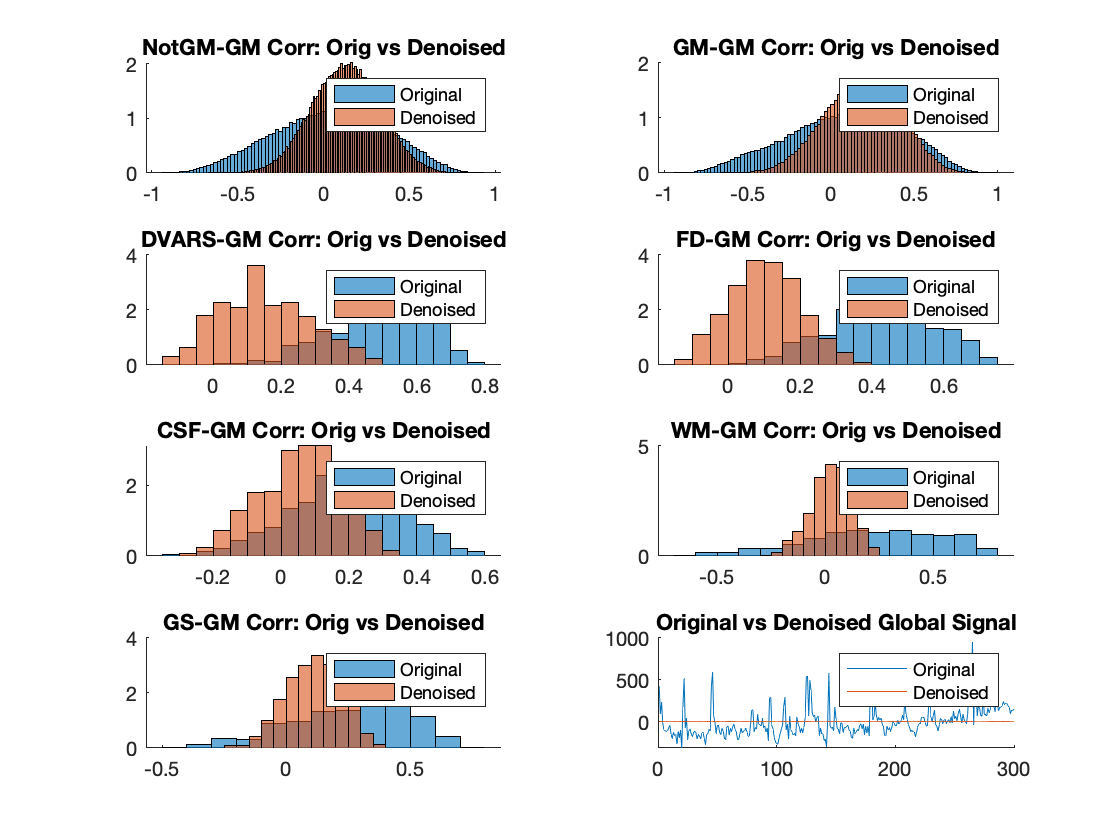

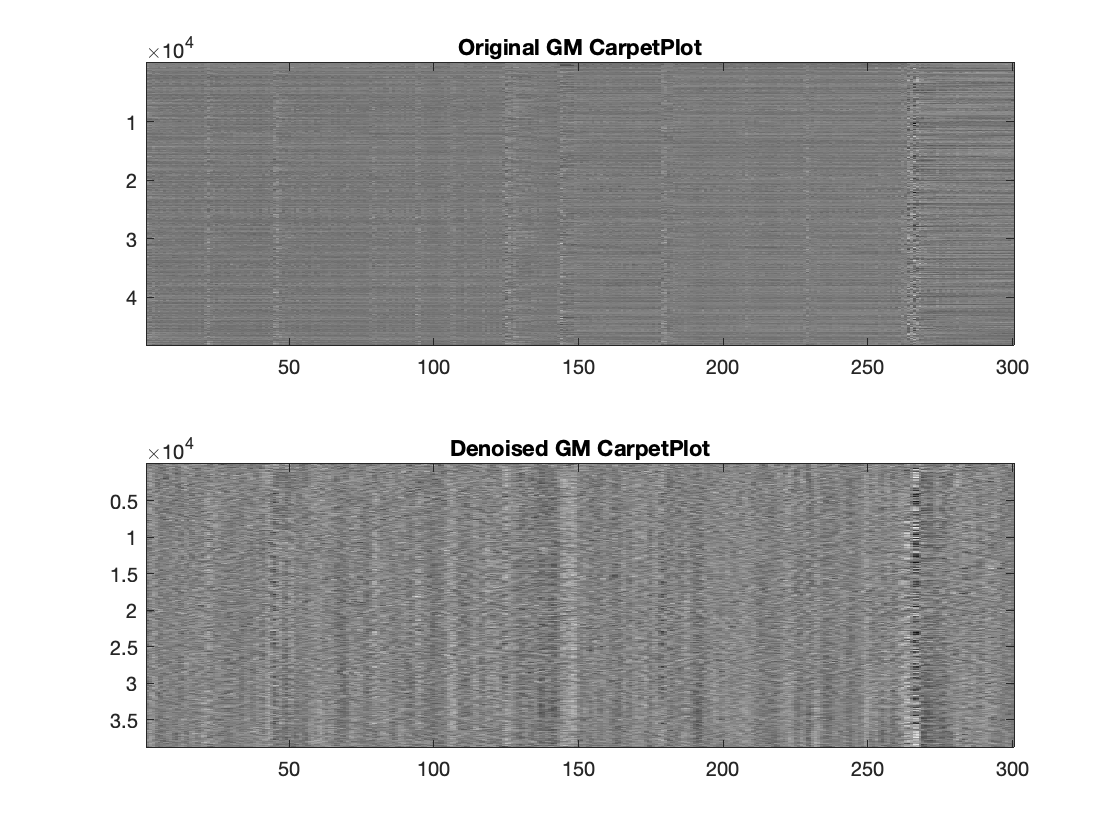

% CADICA_4_QC
% CADICA_3_Clean calculated parcellation text files from Gordon at last of
% denoised files. This script just reads them and runs correlations to plot
% QC

clearvars
close all
home='/Volumes/VectoTec_VectoTech_Media_Rapid/AWESOME/Preproc_ICA_rest/derivatives/CADICA_Updated';
subjects = {'142'};
sessions = {'01'};

cd(home)

for k = 1:length(subjects)
    cd(home)
    currsubjfol = ['sub-', subjects{k}];
    cd(currsubjfol)

    for l = 1:length(sessions)
        currsessfol = ['ses-', sessions{l}];
        cd(currsessfol)

       % confounds:
        confound_place = './confounds_timeseries.csv';
        allconfounds = readtable(confound_place);
        confounds_dvars = table2array(allconfounds(:,{'dvars'}));
        confounds_fd = table2array(allconfounds(:,{'framewise_displacement'}));
        confounds_CSF = table2array(allconfounds(:,{'csf'}));
        confounds_WM = table2array(allconfounds(:,{'white_matter'}));
        confounds_GS = table2array(allconfounds(:,{'global_signal'}));
        
        % Get GM prob mask and create GM mask and not GM mask for denoised
        % and original files
        % currently, we are smoothing and bandpass filtering before ICA
        % selection, and then aggressive denoising (regular regression)
        % noise ICs. This seems to be a good mix of effective for high
        % noise, but still maintaining adequate signal.
        denoised_file = ['./cleaned/sub-', subjects{k}, '_ses-01_task-rest_space-MNI152NLin2009cAsym_desc-CADICA_nonagg_bold.nii.gz'];
        % denoised_file = './cleaned/s_bp_4r_funcfile.nii.gz';
        GM_prob_file = './anatmasks/GMprob_resam.nii.gz';
        funcmask = './funcmask.nii.gz';
        [denoised_GM, denoised_NotGM, denoised_GS, denoised_GS_mean] = getData(denoised_file, funcmask, GM_prob_file);

        orig_file = './funcfile.nii.gz';
        % orig_file = './s_bp_funcfile.nii.gz';
        % orig_file = './cleaned/s_bp_9p_funcfile.nii.gz';
        [orig_GM, orig_NotGM, orig_GS, orig_GS_mean] = getData(orig_file, funcmask, GM_prob_file);
        
        % Now compute relevant correlations
        [denoised_GM_NotGM_corr, denoised_GM_GM_corr] = createHistData(denoised_GM, denoised_NotGM, 500);
        [orig_GM_NotGM_corr, orig_GM_GM_corr] = createHistData(orig_GM, orig_NotGM, 500);

        [denoised_GM_dvars_corr] = createHistConf1DData(denoised_GM, confounds_dvars, 500);
        [orig_GM_dvars_corr] = createHistConf1DData(orig_GM, confounds_dvars, 500);

        [denoised_GM_fd_corr] = createHistConf1DData(denoised_GM, confounds_fd, 500);
        [orig_GM_fd_corr] = createHistConf1DData(orig_GM, confounds_fd, 500);

        [denoised_GM_CSF_corr] = createHistConfData(denoised_GM, confounds_CSF, 500);
        [orig_GM_CSF_corr] = createHistConfData(orig_GM, confounds_CSF, 500);

        [denoised_GM_WM_corr] = createHistConfData(denoised_GM, confounds_WM, 500);
        [orig_GM_WM_corr] = createHistConfData(orig_GM, confounds_WM, 500);

        [denoised_GM_GS_corr] = createHistConfData(denoised_GM, confounds_GS, 500);
        [orig_GM_GS_corr] = createHistConfData(orig_GM, confounds_GS, 500);

        
        tiledlayout(4,2)
        % GM_NotGM corr: Want to see a tighter distribution, centered near
        % 0, if original is significantly right shifted, want to see less
        % of that
        nexttile
        hold on
        title("NotGM-GM Corr: Orig vs Denoised")
        histogram(orig_GM_NotGM_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_NotGM_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off

        % GM_GM corr: Want to see a tighter distribution, hopefully not too
        % shifted toward 0 as compared to original
        nexttile
        hold on
        title("GM-GM Corr: Orig vs Denoised")
        histogram(orig_GM_GM_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_GM_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off
        
        % GM_dvars corr: Want to see a shift toward center for denoised
        % (removal of noise/sudden GS signal shift in GM)
        nexttile
        hold on
        title("DVARS-GM Corr: Orig vs Denoised")
        histogram(orig_GM_dvars_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_dvars_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off

        % GM_fd corr: Want to see a shift toward center for denoised
        % (removal of noise/sudden GS signal shift in GM)
        nexttile
        hold on
        title("FD-GM Corr: Orig vs Denoised")
        histogram(orig_GM_fd_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_fd_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off

         % GM_CSF corr: Want to see a shift toward center for denoised
        % (removal of noise/sudden GS signal shift in GM)
        nexttile
        hold on
        title("CSF-GM Corr: Orig vs Denoised")
        histogram(orig_GM_CSF_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_CSF_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off

        % GM_WM corr: Want to see a shift toward center for denoised
        % (removal of noise/sudden GS signal shift in GM)
        nexttile
        hold on
        title("WM-GM Corr: Orig vs Denoised")
        histogram(orig_GM_WM_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_WM_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off

        % GM_GS corr: Want to see a shift toward center for denoised
        % (removal of noise/sudden GS signal shift in GM)
        nexttile
        hold on
        title("GS-GM Corr: Orig vs Denoised")
        histogram(orig_GM_GS_corr, 'Normalization', 'pdf')
        histogram(denoised_GM_GS_corr, 'Normalization', 'pdf')
        legend('Original', 'Denoised')
        hold off
        
         % Plot GS changes before and after Denoising (spikes should be
        % greatly diminished -- less notable change in GS overall)
        nexttile
        hold on
        title('Original vs Denoised Global Signal')
        plot(orig_GS_mean)
        plot(denoised_GS_mean)
        legend('Original', 'Denoised')
        hold off

        % let's create some carpet plots of the GM
        [N_orig, C_orig, S_orig] = normalize(orig_GM,2);
        N_denoised = normalize(denoised_GM, 2);

        figure
        tiledlayout(2,1)
        nexttile
        imagesc(normalize(orig_GS,2))
        title('Original GM CarpetPlot')
        colormap(gray)

        nexttile
        imagesc(normalize(denoised_GS,2))
        title('Denoised GM CarpetPlot')
        colormap(gray)

    end
end

function [GM, NotGM, Global_Signal, Global_Signal_mean] = getData(funcfile, funcmask, GMprobfile)
     % read in the niftis
     GM_prob_data = niftiread(GMprobfile);
     func_data = niftiread(funcfile);
     funcmask_data = niftiread(funcmask);

    GM_mask = logical(GM_prob_data > 0.75 & funcmask_data == 1);
    NotGM_mask = logical(GM_prob_data < 0.25 & funcmask_data == 1);
    
    % Select the timeseries for GM and not GM and global signal
    global_signal = zeros(sum(funcmask_data(:)), size(func_data, 4));
    GM = zeros(sum(GM_mask(:)), size(func_data, 4));
    NotGM = zeros(sum(NotGM_mask(:)), size(func_data, 4));
    for j = 1:size(func_data, 4)
        curr_func = func_data(:,:,:,j);
        GM(:,j) = curr_func(GM_mask);
        NotGM(:,j) = curr_func(NotGM_mask);
        global_signal(:,j) = curr_func(funcmask_data == 1);
    end
    
    GM = GM(GM(:,1) ~= 0, :);
    NotGM = NotGM(NotGM(:, 1) ~= 0, :);
    Global_Signal = global_signal(global_signal(:, 1) ~= 0, :);
    Global_Signal_mean = mean(global_signal(global_signal(:, 1) ~= 0, :));
    Global_Signal_mean = Global_Signal_mean - mean(Global_Signal_mean);
end

function [GM_NotGM_corr, GM_GM_corr] = createHistData(GM, NotGM, perms)
        % randperm selections
        GM_randperm = randperm(size(GM, 1));
        NotGM_randperm = randperm(size(NotGM, 1));

        % Should center close to 0 (not globally correlated) if it's
        % denoised (e.g., denoised lowered noise)
        GM_NotGM_corr = corr(GM(GM_randperm(1:perms), :)', NotGM(NotGM_randperm(1:perms), :)');
        GM_NotGM_corr = GM_NotGM_corr(tril(GM_NotGM_corr, -1) ~= 0);

        % Should center above 0 (e.g., denoise did not remove true signal)
        GM_corr = corr(GM(GM_randperm(1:perms), :)', GM(GM_randperm(1:perms), :)');
        GM_GM_corr = GM_corr(tril(GM_corr, -1) ~= 0);
end

function [GM_conf1D_corr] = createHistConf1DData(GM, conf, perms)
        % This is for confounds that are calculated in the 1st derivative
        % and absolute value (e.g., dvars, fd)
        GM_randperm = randperm(size(GM, 1));
        % corr conf vs GM diff abs: Should be reduced if denoised
        GM_conf1D_corr = corr(conf(2:end), abs(diff(GM(GM_randperm(1:perms), :)')))';
end

function [GM_conf_corr] = createHistConfData(GM, conf, perms)
        % This is for confounds that are calculated without derivative
        % (e.g., CSF, WM, GS)
        GM_randperm = randperm(size(GM, 1));
        % corr conf vs GM: Should be reduced if denoised
        GM_conf_corr = corr(conf, GM(GM_randperm(1:perms), :)')';
end